## Problem 1

% random number
N = 200;
m_k = randn([1,N]);

% min value
M_0 = -(min(m_k))

M_0 = 2.0127


% normalized sequence
m_nk = 1/M_0 * m_k;
min(m_nk)

ans = -1


% average power
P_m = (1/N) * sum(m_nk.^2)

P_m = 0.2166

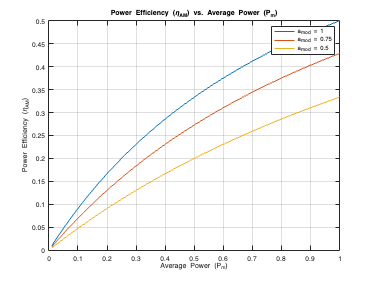


% power efficiency
Pm_range = linspace(0.01, 1, 100);
a_m = [1, 0.75, 0.5];

eta_100 = (a_m(1) * Pm_range) ./ (1 + a_m(1) * Pm_range);
eta_75 = (a_m(2) * Pm_range) ./ (1 + a_m(2) * Pm_range);
eta_50 = (a_m(3) * Pm_range) ./ (1 + a_m(3) * Pm_range);

figure; 
plot(Pm_range, eta_100, 'DisplayName', 'a_{mod} = 1');
hold on; 
plot(Pm_range, eta_75, 'DisplayName', 'a_{mod} = 0.75');
plot(Pm_range, eta_50, 'DisplayName', 'a_{mod} = 0.5');
hold off; 

title('Power Efficiency (\eta_{AM}) vs. Average Power (P_m)');
xlabel('Average Power (P_m)');
ylabel('Power Efficiency (\eta_{AM})');
legend;
grid on;


% values
eta_f_100 = (a_m(1) * P_m) / (1 + a_m(1) * P_m) % a_mod = 1

eta_f_100 = 0.1780

eta_f_75 = (a_m(2) * P_m) / (1 + a_m(2) * P_m) % a_mod = 0.75

eta_f_75 = 0.1397

eta_f_50 = (a_m(3) * P_m) / (1 + a_m(3) * P_m) % a_mod = 0.5

eta_f_50 = 0.0977

## Problem 2

RC = [0.01, 0.1, 1, 10];
B = 10./(2*pi*RC);
f = linspace(-B, B, 1000);
Hf = (1j*2*pi*f)/(1j*2*pi*f+1/RC);

Error using linspace (line 22)
Inputs must be scalars.